# Note 5: Nonlinear DDM

## **Nonlinear Domain Decomposition **

There are 2 main ways to use domain decomposition for nonliear PDEs. One way is to use directly use the domain decomposition techniques on a non-linear problem. In this approach, local nonlinear problems are solved in parallel for each iteration and dirichlet data is exchanged. The other way is to use Newton's method on the global problem. Newton's method involves solving a linear system at each iteration. That linear system can be solved using a Krylov method with a Schwarz preconditioner. These class of methods are called Newton-Krylov-Schwarz (NKS). 

## Regular Newton's Method

Let's start with the easist case: Suppose we discretize the 1D PDE 


$$\left\lbrace \begin{array}{ll}
\ddot{u} \left(x\right)-\kappa \left(x\right){\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0 & a<x<b\\
u\left(x\right)=g_a  & x=a\\
u\left(x\right)=g_b  & x=b
\end{array}\right.$$


and we get the root finding problem $f\left(u\right)=0$ where $f:R^n \to R$ is nonlinear. To solve the problem, we use the regular Newton's method on the global (original) problem. 

The algorithm is: iterate until convergence $\ell =0,1,2,\ldotp \ldotp \ldotp$

  
$$\;\textrm{let}\;u^{\ell +1} =u^{\ell \;} +s^{\ell \;} ,\textrm{where}\;s^{\ell \;} \;\textrm{solves}\;\textrm{the}\;\textrm{linear}\;\textrm{system}\;$$


   
$$J\left(u^{\ell \;} \right)\;s^{\ell \;} =-f\left(u^{\ell \;} \right),\mathrm{where}\;J\left(u\right)\;\mathrm{is}\;\mathrm{the}\;\mathrm{Jacobian}$$


Our formula for $f\left(u_i \right)$ for an interior node $x_i$ is 

    
$$f\left(u_i \right)=\frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-\kappa \left(x_i \right){\left(1+{\max \left(\frac{u_i -u_{i-1} }{h},-\frac{u_{i+1} -u_i }{\;h},0\right)}^2 \right)}^{\frac{3}{2}}$$


Therefore, the derivatives are  

    
$${\left(J\right)}_{\textrm{ij}} =\frac{\partial }{\partial \;u_j }\;f\left(u_i \right)=\left\lbrace \begin{array}{ll}
-\frac{2}{h^2 }-\frac{3}{h^2 }\kappa \;\left(x_i \right)\left(\max \left(u_i -u_{i-1} ,{-u}_{i+1} +u_i ,0\right)\right){\left(1+\max \left(u_i -u_{i-1} ,{-u}_{i+1} +u_i ,0\right)\right)}^{\frac{1}{2}}  & ,i=j\\
\frac{1}{h^2 } & ,\left|i-j\right|=1\\
0 & ,\left|i-j\right|>1
\end{array}\right.$$
 

Therefore, the Jacobian matrix is just a tridiagonal matrix which is inexpensive to solve. 

a = 0;  b = 1;      % domain 
kap = 1;            % curvature 
ga = 0;             % u(a) = ga
gb = 1;             % u(b) = gb
u_exact =@(x) -sqrt(1-x.^2)+1; % exact viscosity solution 

We will use the simple problem $a=0,b=1$with BC $u\left(0\right)=0,\;$$u\left(1\right)=1$ and $\kappa =1$.

#### Fsolve

Below, we compute a solution with $N$ points using MATLAB's fsolve. The use of fsolve does not require a Jacobian but you wouldn't be able to use domain decomposition on it. 

N = 100;
h = (b-a)/(N+1);
X = a+h:h:b-h;
U = zeros(size(X));
f =@(u) makeF(u,ga,gb,h,kap); % the LHS of the PDE 
U = fsolve(f,U); % use nonlinear solver from optimization toolbox


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


#### Newton's Method Implementation

The Jacobian matrix for this problem is known. I do not need to approximate it. I also explicitly construct the matrix. This method is probably not practical for large systems. 

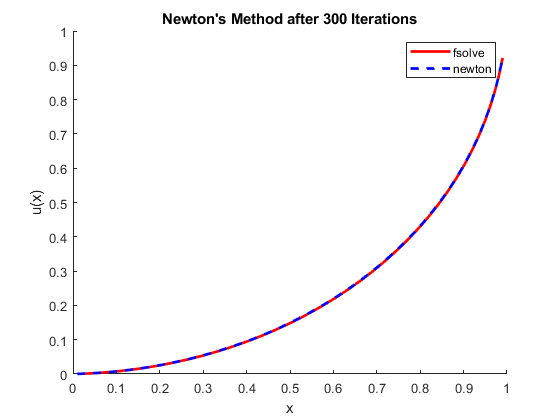

N_iter = 300; 
U_newton = zeros(N,N_iter+1);

for l = 1:N_iter
    J = makeJ(U_newton(:,l),ga,gb,h,kap); % construct the Jacobian 
    
    b = -makeF(U_newton(:,l),ga,gb,h,kap); % make the rhs 
    
    s = J\b; % solve J(u)*s = -f(u) 
    
    U_newton(:,l+1) = U_newton(:,l) + s; % new = old + correction 
    
    if (norm(b) < 1e-3) 
        break
    end
end

figure 
hold on 
plot(X,U,'r','LineWidth',2)
plot(X,U_newton(:,end),'b--','LineWidth',2)
xlabel('x'), ylabel('u(x)')
legend('fsolve','newton')
title("Newton's Method after "+N_iter+" Iterations")

The plot above shows the comparison of the fsolve solution and the barebones Newton's method. The convergence of Newton's method is pretty slow. The system has $N=100$ unknowns. You need $N_{\textrm{iter}} =300$ iterations just to get a decent approximation. 

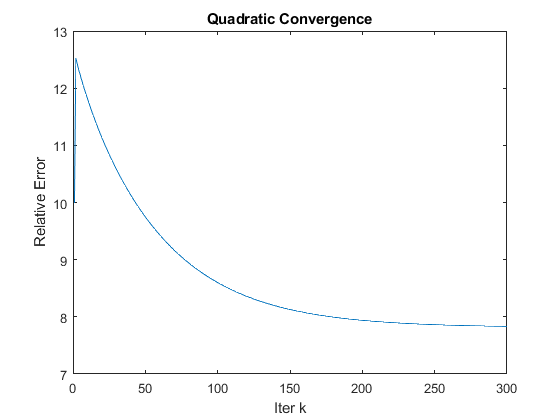

Err = zeros(N_iter,1);
U_exact = u_exact(X);
for i = 1:N_iter
    Err(i) = norm(U_newton(:,i)-U_exact)/norm(U_exact);
end
figure
plot(Err)
xlabel('Iter k')
ylabel('Relative Error')
title('Quadratic Convergence')

## Domain Decomposition Indexing 

We want to do overlapping domain decomposition in 1D. We will do 2 subdomains. We let $N$ be the total number of unique mesh nodes. For odd $N$, the center node is $c=\frac{N+1}{2}$.We choose an integer overlap parameter $\delta >0$ to control how many interior nodes each domain extend over the center node. We form 2 seperate independent systems for each domain by doubling the degree of freedom for shared nodes. That is each local system will have a system of size $N_{\mathrm{loc}} =c+\delta \;$. 

N = 101; 
h = (b-a)/(N+1);
c = (N+1)/2;
delta = 2;
Nloc = c+delta;

x_global = a+h:h:b-h;
x1 = x_global(1:Nloc);
x2 = x_global(end-Nloc+1:end);

## ODDM applied to Newton's Method

For each Newton iteration $\ell =1,2,\ldotp \ldotp \ldotp$, we need to solve 

    $J\left(u^{\ell \;} \right)\;s^{\ell \;} =-f\left(u^{\ell \;} \right)$.

We will ODDM-preconditioned orthodir to solve the systems. See Note 4 for details about this method. 

To implement this method, we need to construct local systems $J_1 \;s_1 =-f_1$ and $J_2 \;s_2 =-f_2$ at every iteration depending on the input $u^{\ell \;}$.

We also need a projection operator which maps the boundary conditions in the DDM. 

N_iter = 300; 
U_newton = zeros(N,N_iter+1);

for l = 1:N_iter
    
    J1 = makeJ1(U_newton(:,l),ga,gb,h,kap);  
    J2 = makeJ2(U_newton(:,l),ga,gb,h,kap);  
    
    b = -makeF(U_newton(:,l),ga,gb,h,kap); % make the rhs 
    
    s = J\b; % solve J(u)*s = -f(u) 
    
    U_newton(:,l+1) = U_newton(:,l) + s; % new = old + correction 
    
    if (norm(b) < 1e-3) 
        break
    end
end

function J = makeJ(u,ga,gb,h,kap)  % jacobian 
n = length(u);
J = gallery('tridiag',n,1/h^2,0,1/h^2);
for i = 1:n
    if (i==1) 
        mm = max([u(i)-ga, -u(i+1)+u(i), 0]);
    elseif(i==n) 
        mm = max([u(i)-u(i-1),-gb+u(i), 0]);
    else 
        mm = max([u(i)-u(i-1),-u(i+1)+u(i), 0]);
    end
    J(i,i) = -2/h^2 - 3/h^2*kap*(1+1/h^2*mm^2)^(1/2)*mm;
end
end


function F = makeF(u,ga,gb,h,kap) % system to find root of 
N = length(u);
F = zeros(N,1);
ih2 = 1/h^2;

F(1) = ih2*(u(2)-2*u(1)+ga)-kap*(1+ih2*max([u(1)-ga,u(1)-u(2),0])^2)^(3/2); % at the left endpoint 

for j = 2:N-1
    F(j) = ih2*(u(j+1)-2*u(j)+u(j-1))-kap*(1+ih2*max([u(j)-u(j-1),u(j)-u(j+1),0])^2)^(3/2); % at the middle points
end

F(N) = ih2*(gb-2*u(N)+u(N-1))-kap*(1+ih2*max([u(N)-u(N-1),u(N)-gb,0])^2)^(3/2); % at the right endpoint
end